# 3.2

- period of cos($\pi$t) is 2, so 2 period of it can be [-2 2]

- we have fs = 1000 so we have 4000 time steps

# note : all paper calcualtion is attched below

%%1
fs = 1000;
t = linspace(-2,2,4000)

t =    -2.0000   -1.9990   -1.9980   -1.9970   -1.9960   -1.9950   -1.9940   -1.9930   -1.9920   -1.9910   -1.9900   -1.9890   -1.9880   -1.9870   -1.9860   -1.9850   -1.9840   -1.9830   -1.9820   -1.9810   -1.9800   -1.9790   -1.9780   -1.9770   -1.9760   -1.9750   -1.9740   -1.9730   -1.9720   -1.9710   -1.9700   -1.9690   -1.9680   -1.9670   -1.9660   -1.9650   -1.9640   -1.9630   -1.9620   -1.9610   -1.9600   -1.9590   -1.9580   -1.9570   -1.9560   -1.9550   -1.9540   -1.9530   -1.9520   -1.9510


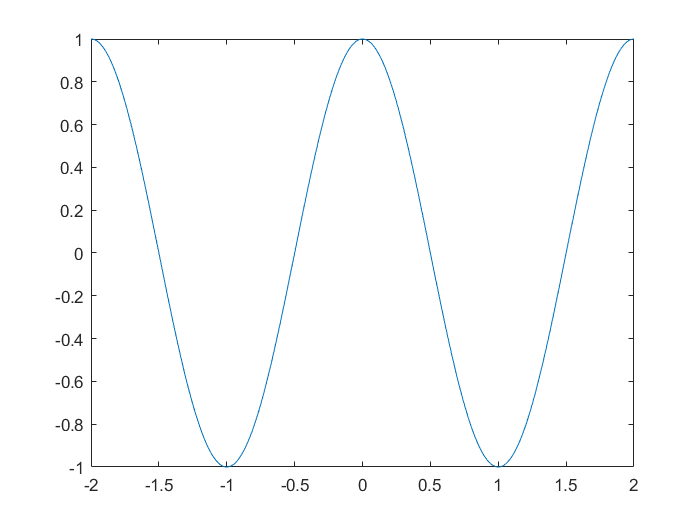

x = cos(pi*t);
plot(t,x);

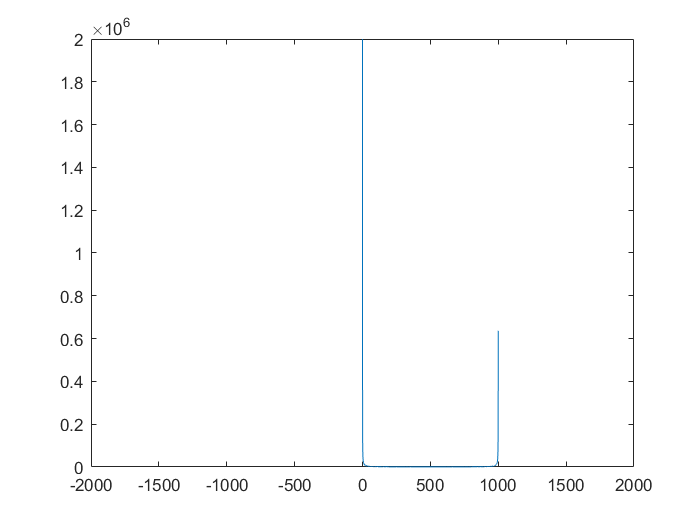

%%2
N = length(t);

f = (0:N-1)*(fs/N);  
plot(f,abs(fft(f)))
xlim([-2000 2000]);

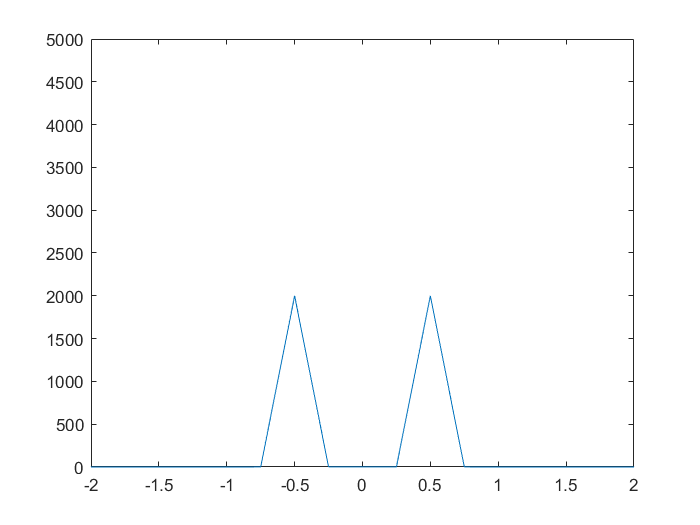

%%3

f = (-N/2:N/2-1)*fs/N;
plot(f,abs(fftshift(fft(x))));
xlim([-2, 2]);
ylim([0, 5000]);

when you use fft the array will be

0 1 2 3 ... fs/2   -fs/2 ... -3 -2 -1

by using fftshift zero frequncy is shifted to center of array so we have:

 -fs/2 ... -3 -2 -1   0 1 2 3 ... fs/2

by using fftshift we can display frequency starts at -fs/2 and ends at fs/2

so we would have a better plot

## **as it is obvious the result is really close to what we calculated and we have two dirac deltas but we have to mention **

## **because we calculated fourier transform with angular frequency on paper it differs a bit in position of dirac delta **

## **functions**

now for two other functions:

### ***f(x)=1***

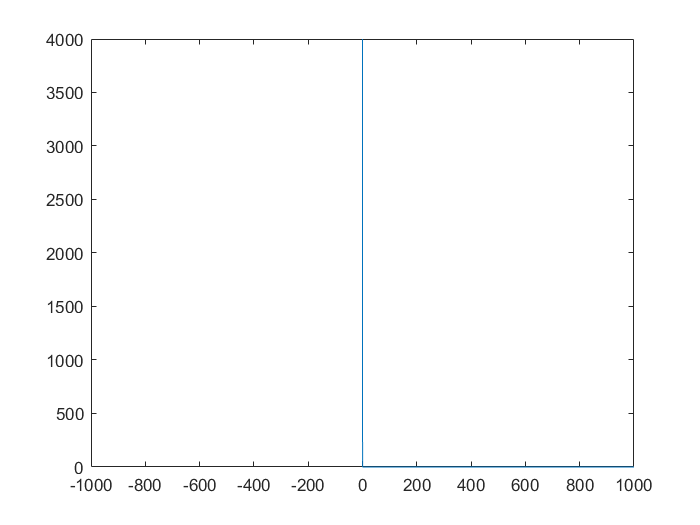

x = ones(size(t)) * 1;

f = (0:N-1)*(fs/N); 
plot(f,abs(fft(x)))
xlim([-1000 1000])

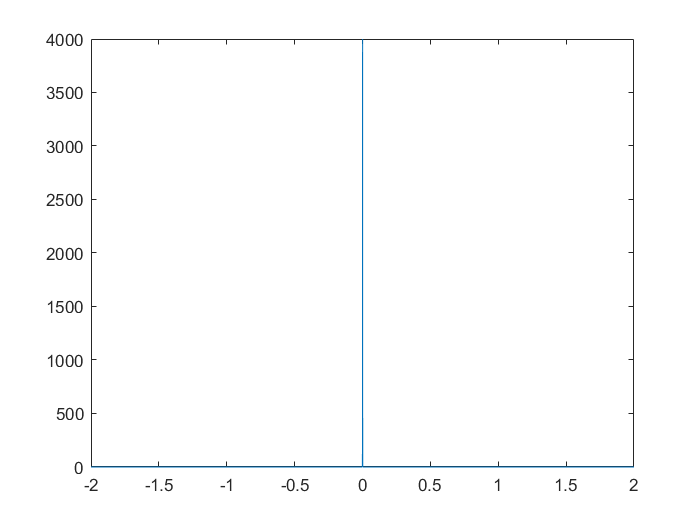

plot(t,fftshift(fft(x)));

## **as it is obvious the result is the same as we calculated on paper**

***f(x)=dirac delta***

x = dirac(t) > 0;
f = (0:N-1)*(fs/N); 
plot(f,abs(fft(x)));

       44100



xlim([-1000 1000])
plot(t,abs(fftshift(fft(f))));
xlim([-1000 1000])

## **as it is obvious the result is the same as we calculated on paper**

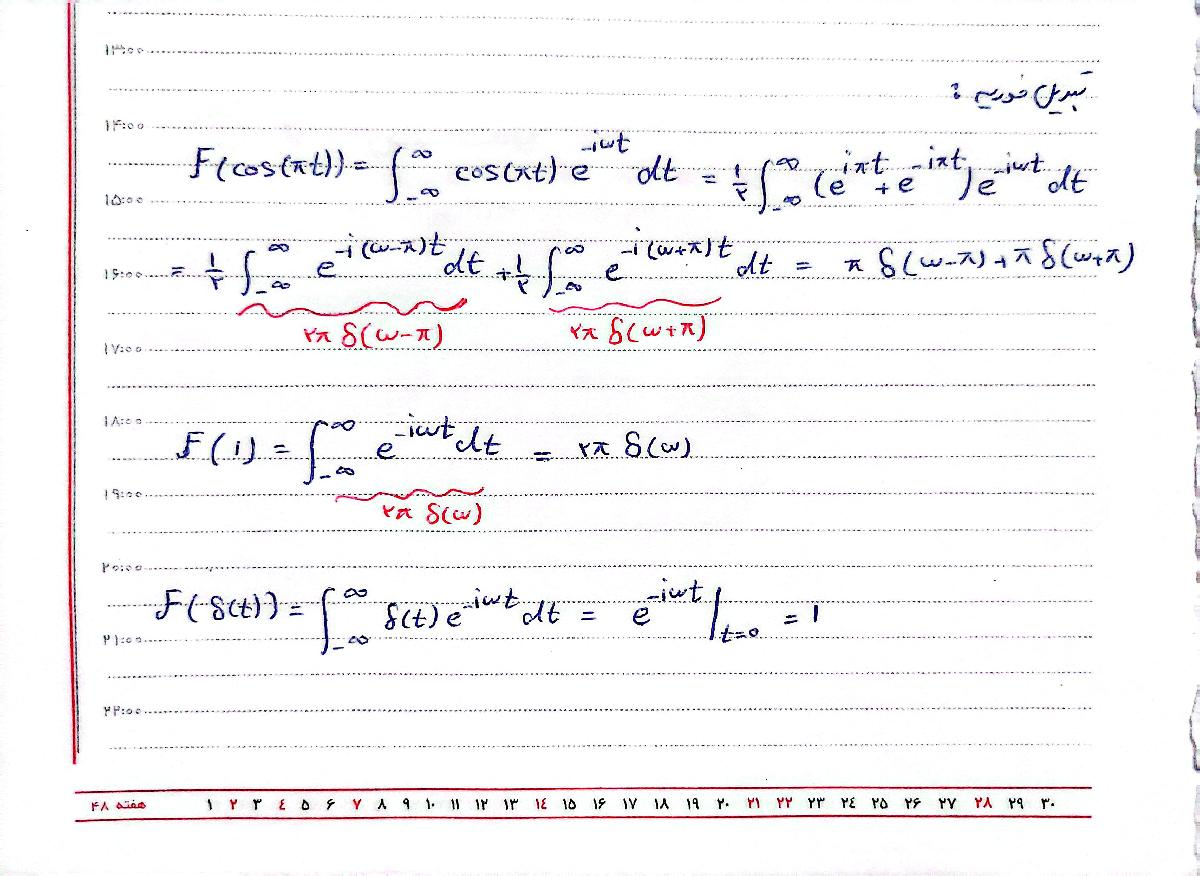

# 3.3

%%1
[y,fs] = audioread("ABITW.mp3");
%sound(y,fs);
disp(fs)

Nyquist theorem in audio signals

The Nyquist theorem is important for capturing audio through digital methods. The average human ear is only sensitive to frequencies between 20 Hz and 20 kHz. Therefore, according to the Nyquist theorem, the optimal sample rate for the human ear is 40 kHz. This is why standard music and audio recording sample rates are close to this value. Any values greater than 40 kHz would be undetectable to most people.

%%2
filename = "times2_freq_ABITW.wav";

       88200



audiowrite(filename,y,2.*fs);
[y,fs1] = audioread(filename);
%sound(y,fs);
disp(fs1)

as we double the frequency the sampling will become faster (2 times)

%%3
filename = "half_freq_ABITW.wav";
audiowrite(filename,y,fs./2);

       22050



[y,fs2] = audioread(filename);
%sound(y,fs);
disp(fs2)

as we halve the frequency the sampling will become slower (2 times)